# **InverseJacobiDN**

[Inverse of the Jacobi elliptic function dn](https://dlmf.nist.gov/22.15)

## Definition


$${\textrm{dn}}^{-1} \left(x\left|m\right.\right)\equiv \left\lbrace \begin{array}{cc}
\mathit{\mathbf{F}}\left(\sqrt{\frac{1-x^2 }{m}}\left|m\right.\right) & m\le 1\\
\frac{{\textrm{cn}}^{-1} \left(x\left|m^{-1} \right.\right)}{\sqrt{m}} & m>1
\end{array}\right.$$



$${\mathrm{dn}}^{-1} \left(x,k\right)\equiv {\mathrm{dn}}^{-1} \left(x\left|k^2 \right.\right)$$


where *m *is the parmeter, *k *is the modulus, $\mathit{\mathbf{F}}\left(x\left|m\right.\right)$ is  Jacobi form of the elliptic integral of the first kind.

Domain:  If $m<0\;$then $1\le x\le \sqrt{1-m}$. If $0\le m\le 1$ then $\sqrt{1-m}\le x<1$ .  If $m>1$ then $\left|x\right|<1$.  For the specified domain, the  codomain  is the set of real numbers.

Basic features:

Special values:

${\mathrm{dn}}^{-1} \left(\sqrt{1-m}\left|m\right.\right)=K\left(m\right)$,    ${\mathrm{dn}}^{-1} \left(1\left|m\right.\right)=0$

${\textrm{dn}}^{-1} \left(x\left|0\right.\right)=\mathrm{NaN}$,    ${\mathrm{dn}}^{-1} \left(x\left|1\right.\right)={\textrm{sech}}^{-1} x$,    ${\textrm{dn}}^{-1} \left(x\left|\infty \right.\right)=0$

Identities:


$${\mathrm{dn}}^{-1} \left(\mathrm{dn}\left(x\left|m\right.\right)\left|m\right.\right)=x,\;\;\;\;\left|x\right|<K\left(m\right)$$



$$\textrm{dn}\left({\textrm{dn}}^{-1} \left(x\left|m\right.\right)\left|m\right.\right)=x$$


$K\left(m\right)$ is the complete elliptic integral of the first kind .

## Syntax

Y = InverseJacobiDN(X,K)

y = ijdn(x,k)

Y = mInverseJacobiDN(X,M)

y = mijdn(x,m)

## Description

**Y = InverseJacobiDN(X,K)** return${\;\mathrm{dn}}^{-1} \left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the sdne size or any of them can be scalar. **InverseJacobiDN** is the wrapper function which calls the functions **ijdn** element-wise via the function **ufun2**.

**y = ijdn(x,k)** return the value of ${\mathrm{dn}}^{-1} \left(x,k\right)$ for argument *x* and the modulus k. It is assumed that the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **ijdn** is the wrapper function which calls the functions **mijdn**.

**Y = mInverseJacobiDN(X,M)** returns ${\mathrm{dn}}^{-1} \left(x\left|m\right.\right)$ for each element of the arrays X and M (pardneter). X and M must be real and the sdne size or any of them can be scalar. **mInverseJacobiDN** is the wrapper function which calls the functions **mijdn** element-wise via the function **ufun2**.

**y = mijdn(x,m)** compute value of ${\mathrm{dn}}^{-1} \left(x\left|m\right.\right)$ for  argument x and the pardneter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mijdn **call the function **melF **for calculation of ${\mathrm{dn}}^{-1} \left(x\left|m\right.\right)$ ([1-2]).

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
x = 1.01*sqrt(1-k^2);
[ijdn(x,k), InverseJacobiDN(x,k), mijdn(x,k^2), mInverseJacobiDN(x,k^2)]

ans =    1.400230500571429   1.400230500571429   1.400230500571429   1.400230500571429


% Maple 1.400230500571429_06


Accuracy.

fprintf('%.16g\n',ijdn(0.9,0.9)) 

0.5237929007809741


%  Maple  0.5237929007809741_56

fprintf('%.16g\n',mijdn(2,-4)) 

0.7663454616725307


% Maple 0.7663454616725306_65

Special values

m = -3; % m<1
disp(mijdn(-1,m)-2*melK(m))

   NaN



disp(mijdn(0,m) - melK(m))  % m < 1 !!!

   NaN



mijdn(1,m)

ans = 0

x=0.5;
disp(mijdn(x,0)) 

   NaN



disp(mijdn(x,1) - asech(x))

     0



Identities

m = -0.2;
x = (1+sqrt(1-m))/2; % |x| <= 1
disp(mJacobiDN(mInverseJacobiDN(x,m),m)-x)

    -2.220446049250313e-16



%disp(mInverseJacobiDN(x,m) - mpEllipticF(asin(sqrt((1-x^2)/m)),m))
k = 0.99995;
x = 0.9999*elK(k);
disp(InverseJacobiDN(JacobiDN(x,k),k)-x)

    -1.819106643097257e-09



x= (1+sqrt(1-k^2))/2; 
disp(InverseJacobiDN(x,k)-InverseJacobiCN(x,1/k)/k)

     0



**Vector input**

m = [0.1, 0.5, 0.89, 0.99995];
x = 0.9999992;
disp(mInverseJacobiDN(x,m)-mInverseJacobiCN(x,1./m)./sqrt(m))

   1.0e-18 *

                   0   0.216840434497101  -0.216840434497101                   0



**Matrix input**

m = [0.1, 0.5; 0.89, 0.99995];
x = 0.9999992;
disp(mInverseJacobiDN(x,m)-mInverseJacobiCN(x,1./m)./sqrt(m))

   1.0e-18 *

                   0   0.216840434497101
  -0.216840434497101                   0



## **Plot **

**Example 1**

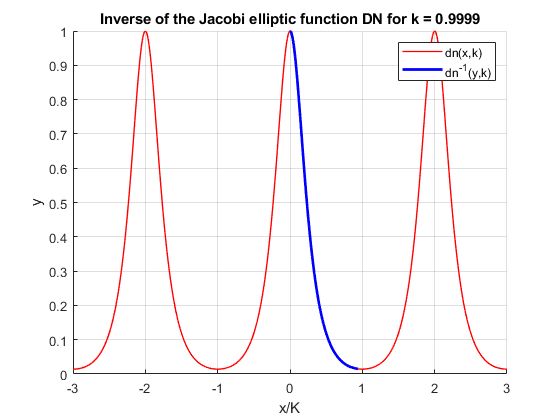

figure
hold on
x=-3:0.01:3;
k = 0.9999;
if k < 1
    M = elK(k);
    xlabel('x/K')
else
    M = 1;
    xlabel('x')
end
plot(x,JacobiDN(M*x,k),'LineWidth',1.0,'Color','red')
x=-1:0.001:1;
plot(InverseJacobiDN(x,k)/M,x,'LineWidth',2,'Color','blue')
legend('dn(x,k)','dn^{-1}(y,k)') %,'Position','best')

ylabel('y')
%xlim([-1.1 1.1])
%ylim([-3 3])
title(sprintf('Inverse of the Jacobi elliptic function DN for k = %g',k))
grid on
hold off

**Example 2**

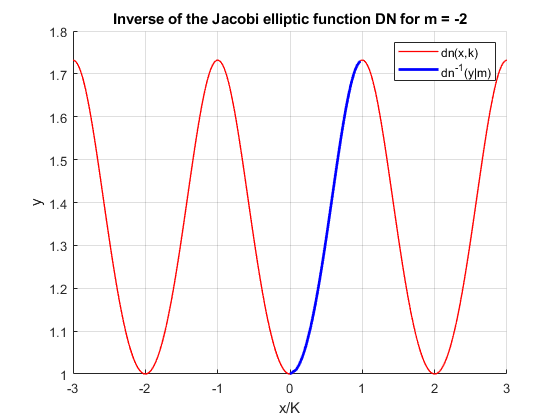

figure
hold on
x=-3:0.01:3;
m = -2;
if m < 1
    M = melK(m);
    xlabel('x/K')
else
    M = 1;
    xlabel('x')
end
plot(x,mJacobiDN(M*x,m),'LineWidth',1.0,'Color','red')
x=-1:0.01:12;
plot(mInverseJacobiDN(x,m)/M,x,'LineWidth',2,'Color','blue')
legend('dn(x,k)','dn^{-1}(y|m)') %,'Position','best')

ylabel('y')
%xlim([-1.1 1.1])
%ylim([-3 3])
title(sprintf('Inverse of the Jacobi elliptic function DN for m = %g',m))
grid on
hold off

**Example 3**

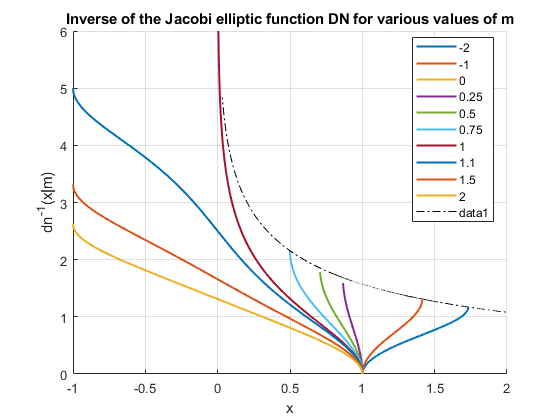

figure
hold on
X = -1:0.001:2;
M = [-2,-1,0,0.25,0.5,0.75,1,1.1,1.5,2];
SN = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mInverseJacobiDN(X,M(i));
end
plot(X,SN,'LineWidth',1.5)
axis([min(X) max(X) 0 6])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Inverse of the Jacobi elliptic function DN for various values of m')
N=-12:0.001:1;
X = sqrt(1-N);
plot(X,mInverseJacobiDN(X,N),'k-.')
xlabel('x')
ylabel('dn^{-1}(x|m)')

**Example 4**

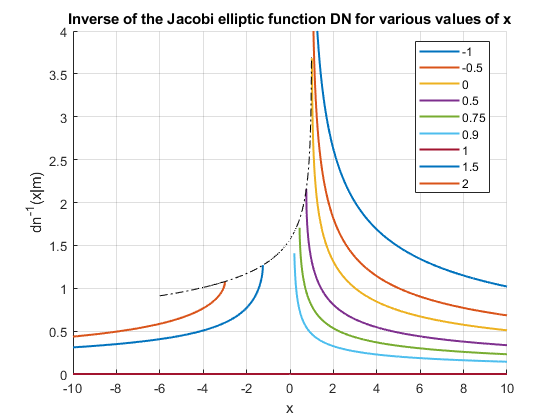

figure
hold on
M = -10:0.01:10;
X = [-1,-0.5,0,0.5,0.75,0.9,1,1.5,2];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mInverseJacobiDN(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
%axis([min(M) max(M) -3 3])
ylim([0  4])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Inverse of the Jacobi elliptic function DN for various values of x')
xlabel('x')
ylabel('dn^{-1}(x|m)')
M = -6:0.01:1;
F = mInverseJacobiDN(sqrt(1-M),M);
plot(M,F,'k-.')
%plot(M,-F)
hold off

**Example 5**

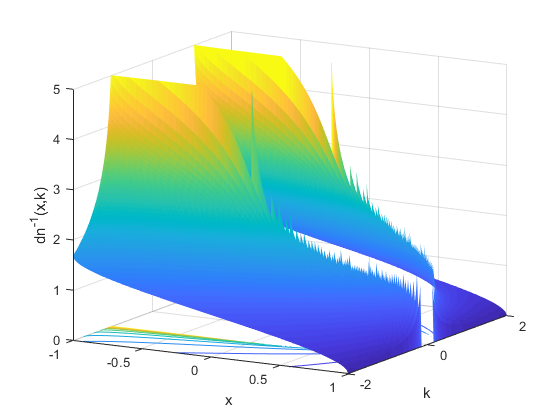

figure
x=-1:0.01:1;
k=-2:0.01:2;
zz = 5;
[X,K]=meshgrid(x,k);
hs=surfc(X,K,InverseJacobiDN(X,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 0.5;
hc.LevelList = 0:zz/10:zz;
view([30 15])
caxis([0 zz])
xlabel('x')
ylabel('k')
zlabel('dn^{-1}(x,k)')
zlim([0 zz])
grid on

**Example 6**

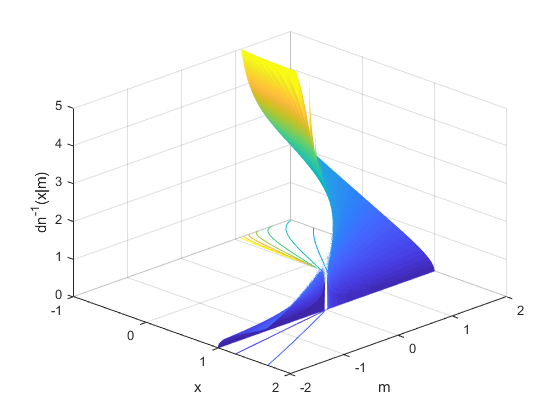

figure
x=-1:0.01:2;
m=-2:0.01:2;
zz = 5;
[X,M]=meshgrid(x,m);
hs=surfc(X,M,mInverseJacobiDN(X,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = 0;
hc.LineWidth = 0.5;
hc.LevelList = 0:zz/10:zz;
view([45 30])
caxis([0 zz])
xlabel('x')
ylabel('m')
zlabel('dn^{-1}(x|m)')
zlim([0 zz])
grid on

**Example 7**

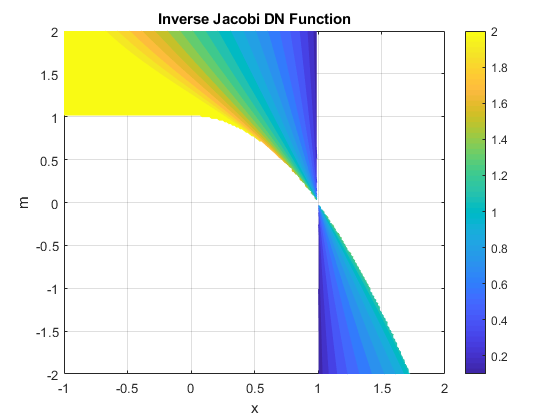

figure
f = @(x,m)mInverseJacobiDN(x,m);
fcontour(f,[-1 2 -2 2],'Fill','on','LevelList',-2:0.1:2,'MeshDensity',200)
title('Inverse Jacobi DN Function')
colorbar
xlabel('x')
ylabel('m')
grid on

**Example 8**

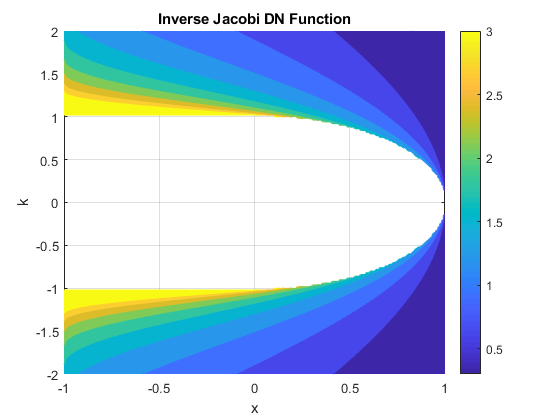

figure
f = @(x,k)InverseJacobiDN(x,k);
fcontour(f,[-1 1 -2 2],'Fill','on','LevelList',-3:0.3:3,'MeshDensity',200)
title('Inverse Jacobi DN Function')
colorbar
xlabel('x')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

## See Also